syms x y

% Exercise 2
fx = y + 2*x - x^3

$$fx = -x^{3}+2\,x+y$$

fy = - x + 2*y - 2*y^3

$$fy = -2\,y^{3}+2\,y-x$$

% setting the matlab function for our system
f_lmb = @(t,z) [z(2) + 2*z(1) - z(1)^3; - z(1) + 2*z(2) - 2*z(2)^3];

% 1. CALCULATE THE FIXED POINTS
fixPts = solve([fx; fy], [x; y]);
fixPts = double([fixPts.x'; fixPts.y']);
fixPts = fixPts(:, 1)

fixPts =      0
     0



% Computing the jacobian matrix and the eigenvalues for the fixed points
JacFixPts = zeros(2, 2, size(fixPts, 2));
eigenvalues = zeros(size(fixPts, 2), 2);

for k = 1:size(fixPts, 2)
    JacFixPts(:,:,k) = double(subs(jacobian([fx, fy], [x, y]), {x, y}, {fixPts(1, k), fixPts(2, k)}));
    eigenvalues(k, :) = eig(JacFixPts(:,:,k));
end

% 2. IDENTIFY AND CLASSIFY THE FIXED POINTS: HYPERBOLIC VS NON-HYPERBOLIC
for k =1:size(fixPts, 2)
    if all(real(eigenvalues(k, :)) == 0)
        fprintf('Fixed point at (%f, %f) is hyperbolic.\n', fixPts(1, k), fixPts(2, k));
    else
        fprintf('Fixed point at (%f, %f) is not hyperbolic.\n', fixPts(1, k), fixPts(2, k));
    end
end

Fixed point at (0.000000, 0.000000) is not hyperbolic.



% Represent the fixed points and the eigenvalues
h1 = figure;
hold on;
grid on;
fpts = plot(fixPts(1,:), fixPts(2,:), 'o', 'MarkerFaceColor', 'r');


% 3. COMPUTE THE NULLCLINES
xcline_x = solve(fx == 0, x);
ycline_y = solve(fy == 0, y);

% Representing the nullclines
nullX = fimplicit(fx, [-5 5 -5 5], 'r--', 'LineWidth', 1.5);
nullY = fimplicit(fy, [-5 5 -5 5], 'g--', 'LineWidth', 1.5);

% 5. REPRESENT FLOW IN A GRID 10X10
% Campo vectorial
N = 10; % tamaño de la cuadrícula
xlin = linspace(-5, 5, N);
ylin = linspace(-5, 5, N);
[Xgrid, Ygrid] = meshgrid(xlin, ylin);

fx_grid = subs(fx, [x, y], {Xgrid, Ygrid});
fy_grid = subs(fy, [x, y], {Xgrid, Ygrid});

magnitude = sqrt(fx_grid.^2 + fy_grid.^2);
fx_normalized = fx_grid ./ magnitude;
fy_normalized = fy_grid ./ magnitude;

flow = quiver(Xgrid, Ygrid, fx_normalized, fy_normalized, 'AutoScale', 'on', 'AutoScaleFactor', 0.25, 'Color', 'k');

axis([-5 5 -5 5]);
xlabel('x');
ylabel('y');
title('Campo vectorial con puntos fijos, eigenvalores y nullclines');

% REPRESENT AN  UPWARD RADIUS PATH
y0 = [0.5 0.5]

y0 =     0.5000    0.5000


t0 = 0.5; tf = 50;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb,tspam, y0);
traj1 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

% REPRESENT A DOWNWARD RADIUS PATH
y0 = [3 2]

y0 =      3     2


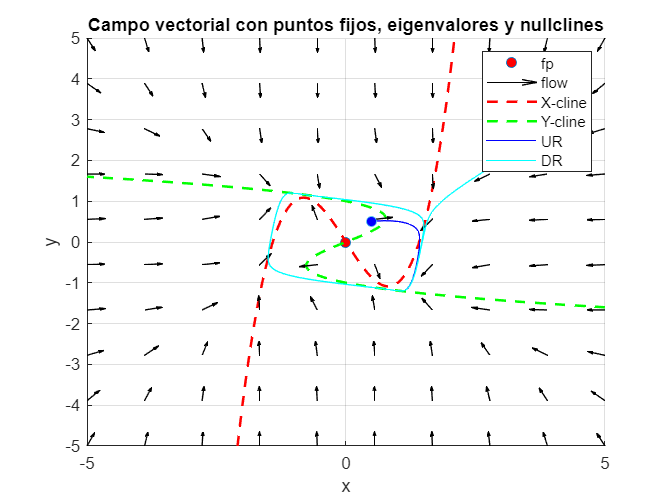

t0 = 0.5; tf = 50;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb,tspam, y0);
traj2 = plot(ys(:,1),ys(:,2),'cyan-'); plot(y0(1),y0(2),'o','MarkerFaceColor','cyan');

legend([fpts flow nullX nullY traj1 traj2],{'fp', 'flow', 'X-cline', 'Y-cline', 'UR', 'DR'},'Location', 'NorthEast')


disp('As it can be seen in the phase diagram, this system has a limit cycle')

As it can be seen in the phase diagram, this system has a limit cycle
